# Comparison of Steady Firing Rate and Inverse of Interspike Interval as a Function of Applied Current


tau_ref = 2.5e-3;   % refractory period (ms)
tnext = tau_ref/dt; % time until next spike can be fired 
tmax2 = 5;          % simulation time (s)
tvec2 = 0:dt:tmax2; % time vector

Iapp1b = 250e-12:20e-12:650e-12;% applied current vector
V1b = zeros(size(tvec2));       % membrane potential vector
V1b(1) = El;                    % set initial voltage to resting potential
Grsa1b = zeros(size(tvec2));    % adaptive conductance vector
spiket1b = zeros(size(tvec2));  % spike time vector
steady1b = zeros(size(Iapp1b)); % steady-state firing rate vector
f_fr = zeros(size(Iapp1b));     % first ISI firing rate vector


## Firing Simulations

% loop through applied currents
for k = 1:length(Iapp1b)
    spiket1b = zeros(size(tvec2)); % reset spike times

    % loop through time steps
    for i = 2:length(tvec2)
        % calculate membrane potential derivative
        dVdt = 1/Cm*((El - V1b(i-1))/Rm + Grsa1b(i-1)*(Ek-V1b(i-1)) + Iapp1b(k));
        % update membrane potential
        V1b(i) = V1b(i-1) + dVdt*dt;
        % update sra conductance
        Grsa1b(i) = Grsa1b(i-1) - Grsa1b(i-1)/tausra*dt;
        % after a spike, fix membrane potential to Vreset for tau_ref period

        if spiket1b(i) == -1
            V1b(i) = Vreset;
        end

        % if threshold is reached, generate a spike
        if V1b(i) > Vth
            % reset membrane potential and increase sra conductance
            V1b(i) = Vreset;
            Grsa1b(i) = Grsa1b(i) + deltaGsra;

            % mark spike time and refractory period
            spiket1b(i) = 1;
            for j = 1:tnext
                spiket1b(i+j) = -1;
            end
        end
    end
    % calculate firing rate and update firing rate vectors
    peak_ind = find(spiket1b == 1);
    if isempty(peak_ind)
    f_fr(k) = 0;
    else
    f_fr(k) = 1/((peak_ind(2) - peak_ind(1))*(10^(-4))); % Calculate inverse of ISI
    end
    steady1b(k) = length(peak_ind)/tmax2;
end

## Plot Figures

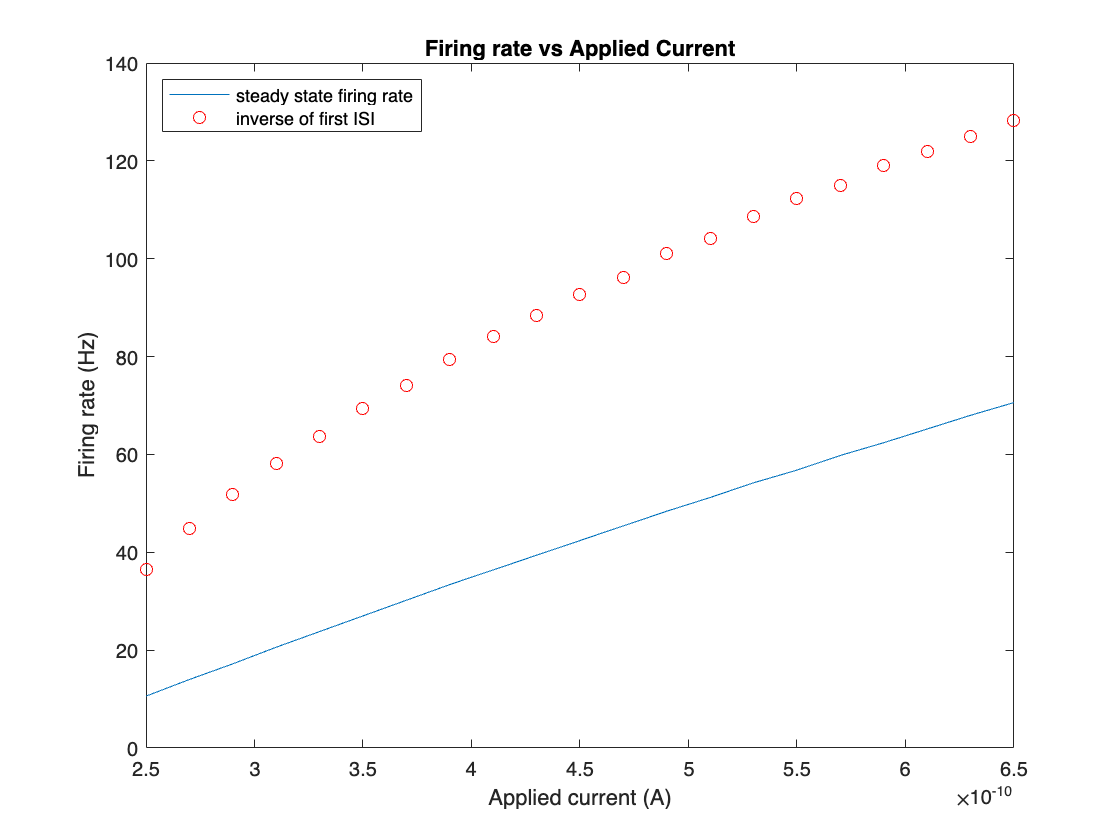

figure;
plot(Iapp1b, steady1b, Iapp1b, f_fr, 'ro')
title('Firing rate vs Applied Current')
xlabel('Applied current (A)'), ylabel('Firing rate (Hz)')
legend('steady state firing rate', 'inverse of first ISI', location='northwest')